Лабораторная работа №3

Пространственный робот с 3-мя звеньями

Топольницкий А.

Вариант №53

Задание:

- Изучить предоставленные примеры

- Создать структуру робота в соответствии с вариантом

- Реализовать все виды управления и в качестве траектории выбрать любую сложную траекторию:

- Управление на основе ПИД с обратной кинематикой

- Линеаризацию по обратной связи с обратной кинематикой

- Импеданс с компенсацией силы тяжести

- Промоделировать контакт - выполнить мягкое взаимодействие с объектом, расположенным на столе.

Вариант №53, исходные данные:

Три сочленения: первое - вращательное, второе и третье - призматическое;

Вращение происходит вокруг оси Х, линейное перемещение второго звена вдоль Х, третьего - вдоль Z

Исходное положение в случае вращательного соединения = 0 [рад]

Исходное положение в случае призматического соединения = li / 2 [м]

Все звенья имеют квадратное поперечное сечение с указанной шириной

### Управление на основе ПИД с обратной кинематикой

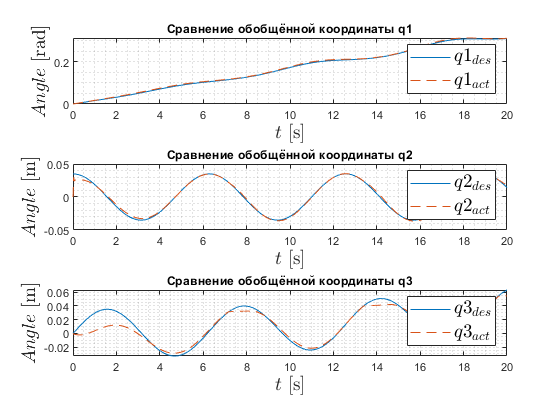

% масса звеньев в килограммах 
m1 = 6.287;
m2 = 17.506;
m3 = 6.494; 

% длины звеньев в метрах
l1 = 0.45;
l2 = 0.22;
l3 = 0.28;

% ширина звеньев в метрах
w1 = 0.135;
w2 = 0.066;
w3 = 0.084;
AB = [w1/2 w1/2 l1];
BC = [l2 w2/2 w2/2];
CD = [w3/2 w3/2 l3];
Base = [0.3*l1 0.3*l1 0.3*l1];
kp = 100;
ki = 100;
kd = 100;

kp1 = 100;
ki1 = 100;
kd1 = 100;

kp2 = 100;
ki2 = 100;
kd2 = 100;

Part4sm_lab4_pid


figure;
subplot(3,1,1);
plot(out.qs.q1_des.time, out.qs.q1_des.Data)
hold on
plot(out.qs.q1_act.time,out.qs.q1_act.Data, 'LineStyle','--')
grid minor;
legend('$q1_{des}$', '$q1_{act}$',  'fontsize',14,'interpreter','latex');
ylabel('$Angle$ [rad]', 'fontsize',14,'interpreter','latex');
xlabel('$t$ [s]', 'fontsize',14,'interpreter','latex');
title('Сравнение обобщённой координаты q1')
subplot(3,1,2);
plot(out.qs.q2_des.time, out.qs.q2_des.Data)
hold on
plot(out.qs.q2_act.time,out.qs.q2_act.Data,'LineStyle','--')
grid minor;
legend('$q2_{des}$', '$q2_{act}$',  'fontsize',14,'interpreter','latex');
ylabel('$Angle$ [m]', 'fontsize',14,'interpreter','latex');
xlabel('$t$ [s]', 'fontsize',14,'interpreter','latex');
title('Сравнение обобщённой координаты q2')
subplot(3,1,3);
plot(out.qs.q3_des.time, out.qs.q3_des.Data)
hold on
plot(out.qs.q3_act.time,out.qs.q3_act.Data,'LineStyle','--')
grid minor;
legend('$q3_{des}$', '$q3_{act}$',  'fontsize',14,'interpreter','latex');
ylabel('$Angle$ [m]', 'fontsize',14,'interpreter','latex');
xlabel('$t$ [s]', 'fontsize',14,'interpreter','latex');
title('Сравнение обобщённой координаты q3')

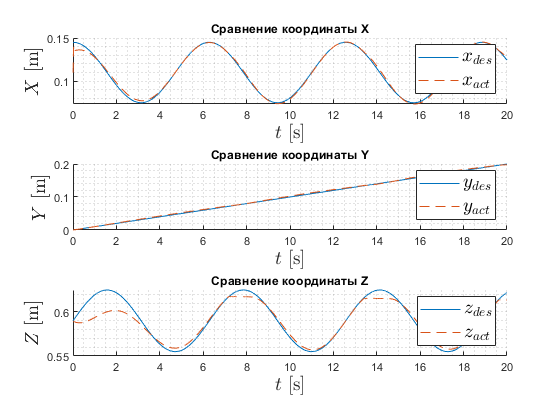

figure;
subplot(3,1,1)
hold on
plot(out.pos.p_des.time, out.pos.p_des.data(:,1))
plot(out.pos.p_sens.x.time, out.pos.p_sens.x.data,'LineStyle','--')
grid minor
legend('$x_{des}$', '$x_{act}$',  'fontsize',14,'interpreter','latex');
ylabel('$X$ [m]', 'fontsize',14,'interpreter','latex');
xlabel('$t$ [s]', 'fontsize',14,'interpreter','latex');
title('Сравнение координаты Х')
subplot(3,1,2)
hold on
plot(out.pos.p_des.time, out.pos.p_des.data(:,2))
plot(out.pos.p_sens.y.time, out.pos.p_sens.y.data,'LineStyle','--')
grid minor
legend('$y_{des}$', '$y_{act}$',  'fontsize',14,'interpreter','latex');
ylabel('$Y$ [m]', 'fontsize',14,'interpreter','latex');
xlabel('$t$ [s]', 'fontsize',14,'interpreter','latex');
title('Сравнение координаты Y')
subplot(3,1,3)
hold on
plot(out.pos.p_des.time, out.pos.p_des.data(:,3))
plot(out.pos.p_sens.z.time, out.pos.p_sens.z.data,'LineStyle','--')
grid minor
legend('$z_{des}$', '$z_{act}$',  'fontsize',14,'interpreter','latex');
ylabel('$Z$ [m]', 'fontsize',14,'interpreter','latex');
xlabel('$t$ [s]', 'fontsize',14,'interpreter','latex');
title('Сравнение координаты Z')

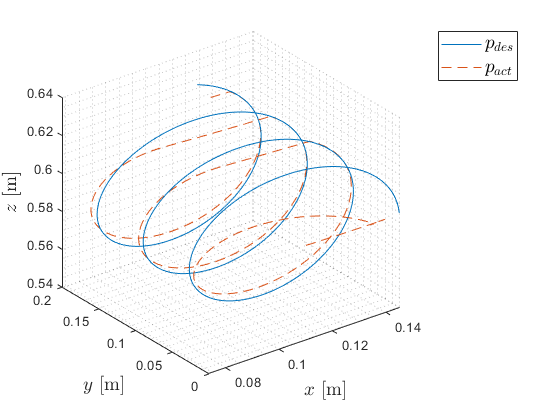

figure;
plot3(out.pos.p_des.data(:,1),out.pos.p_des.data(:,2),out.pos.p_des.data(:,3))
hold on
plot3(out.pos.p_sens.x.data,out.pos.p_sens.y.data,out.pos.p_sens.z.data, 'LineStyle','--')
legend('$p_{des}$', '$p_{act}$',  'fontsize',14,'interpreter','latex')
xlabel('$x$ [m]', 'fontsize',14,'interpreter','latex');
ylabel('$y$ [m]', 'fontsize',14,'interpreter','latex');
zlabel('$z$ [m]', 'fontsize',14,'interpreter','latex');
grid minor

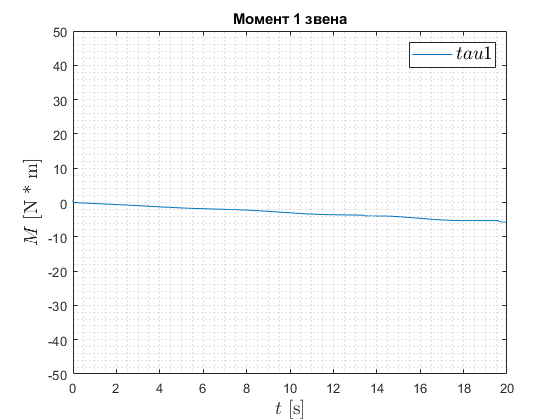



figure;
plot(out.tau.tau1.time,out.tau.tau1.data)
grid minor
legend('$tau1$','fontsize',14,'interpreter','latex');
ylabel('$M$ [N * m]', 'fontsize',14,'interpreter','latex');
xlabel('$t$ [s]', 'fontsize',14,'interpreter','latex');
title('Момент 1 звена')
ylim([-50, 50])

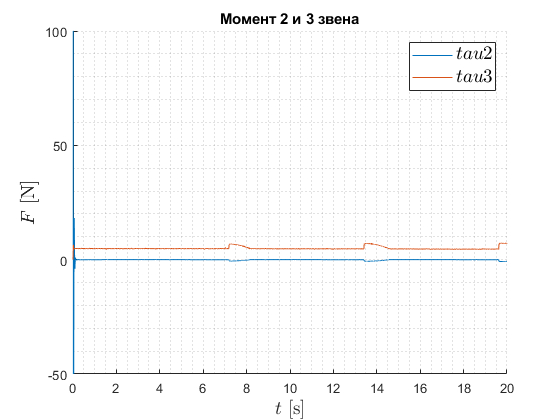

figure;
hold on 
plot(out.tau.tau2.time,out.tau.tau2.data)
plot(out.tau.tau3.time,out.tau.tau3.data)
grid minor
legend('$tau2$', '$tau3$',  'fontsize',14,'interpreter','latex');
ylabel('$F$ [N]', 'fontsize',14,'interpreter','latex');
xlabel('$t$ [s]', 'fontsize',14,'interpreter','latex');
title('Момент 2 и 3 звена')
ylim([-50, 100])

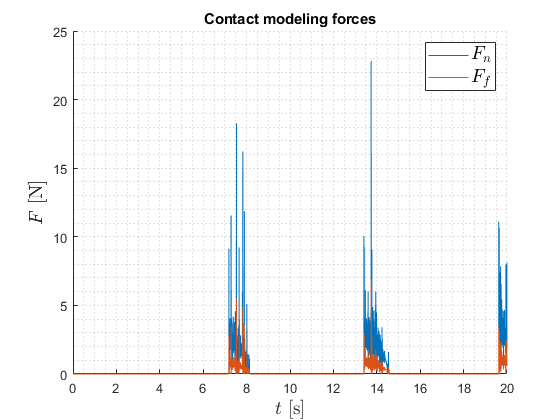


figure;
hold on
plot(out.obj.Norm.time, out.obj.Norm.Data)
plot(out.obj.Fric.time, out.obj.Fric.Data)
grid minor
legend('$F_n$', '$F_f$', 'fontsize',14,'interpreter','latex')
xlabel('$t$ [s]', 'fontsize',14,'interpreter','latex')
ylabel('$F$ [N]', 'fontsize',14,'interpreter','latex')
title('Contact modeling forces')

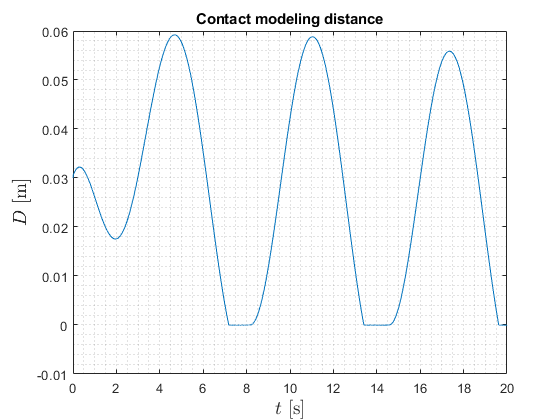

figure;
plot(out.obj.Dis.time, out.obj.Dis.Data)
title('Contact modeling distance')
grid minor
xlabel('$t$ [s]', 'fontsize',14,'interpreter','latex');
ylabel('$D$ [m]', 'fontsize',14,'interpreter','latex');